# MANOJ KUMAR - `2048015`

## Lab 6 - Write a program to demonstrate edge detection.

## `10/03/21`

### Image Edge Detection Operators - Gradient Based

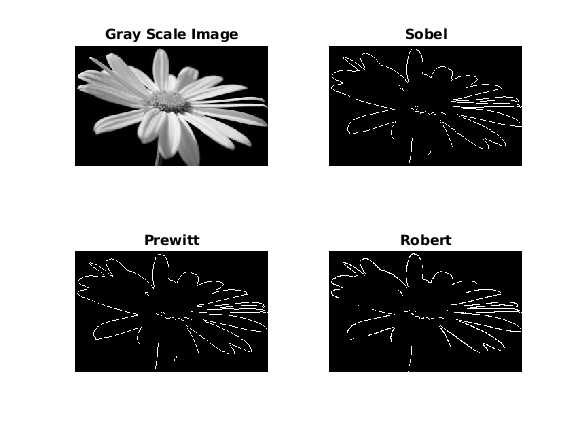

% importing the imgae 
I = rgb2gray(imread("flower.jpeg")); 
subplot(2, 2, 1), imshow(I); title("Gray Scale Image"); 


% Sobel Edge Detection 
J = edge(I, 'Sobel'); 
subplot(2, 2, 2), imshow(J); title("Sobel"); 

% Prewitt Edge detection 
K = edge(I, 'Prewitt'); 
subplot(2, 2, 3), imshow(K); title("Prewitt"); 

% Robert Edge Detection 
L = edge(I, 'Roberts'); 
subplot(2, 2, 4), imshow(L); title("Robert"); 

### Image Edge Detection Operators - Guassian Based

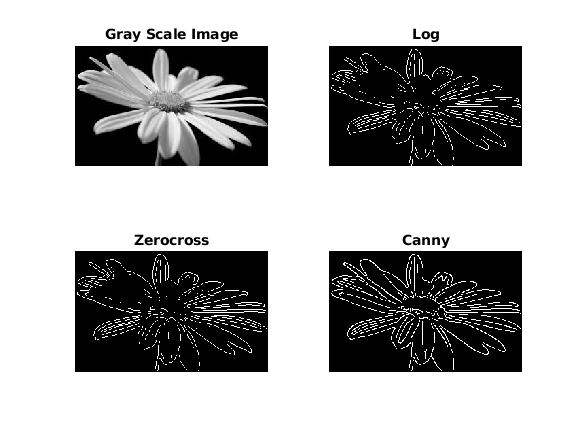


subplot(2, 2, 1), imshow(I); title("Gray Scale Image"); 

% Log Edge Detection 
M = edge(I, 'log'); 
subplot(2, 2, 2), imshow(M); title("Log"); 

% Zerocross Edge Detection 
M = edge(I, 'zerocross'); 
subplot(2, 2, 3), imshow(M); title("Zerocross"); 

% Canny Edge Detection 
N = edge(I, 'Canny'); 
subplot(2, 2, 4), imshow(N); title("Canny"); 

## Image Edge Detection - Horizontal, Vertical (X and Y axis direction masks)

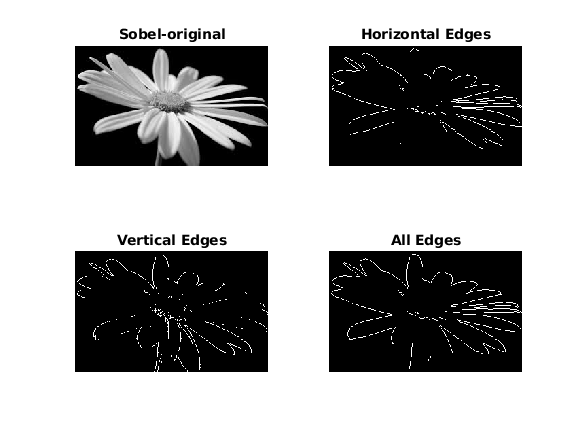

% Apply Sobel Operator

clc;
mycolourimage = imread("flower.jpeg");
myimage = rgb2gray(mycolourimage);


figure;
subplot(2,2,1);imshow(myimage); title('Sobel-original');

% Display only the horizontal Edges
sobelhz = edge(myimage,'sobel','horizontal');
subplot(2,2,2);imshow(sobelhz,[]); title('Horizontal Edges');

% Display only the vertical Edges
sobelvrt = edge(myimage,'sobel','vertical');
subplot(2,2,3);imshow(sobelvrt,[]); title('Vertical Edges');

% Display both horizontal and vertical Edges
sobelvrthz = edge(myimage,'sobel','both');
subplot(2,2,4);imshow(sobelvrthz,[]); title('All Edges');

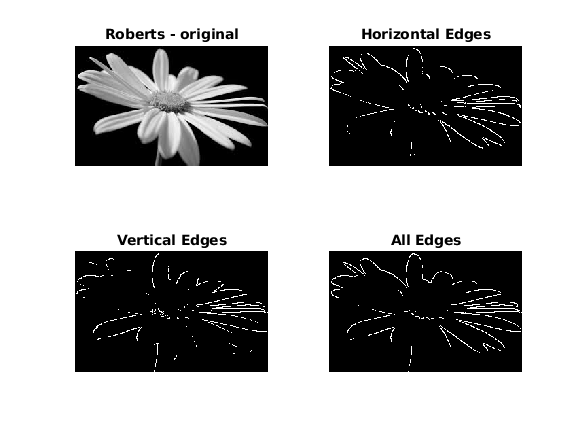

% Apply Roberts Operator

clc;

figure;
subplot(2,2,1);imshow(myimage); title('Roberts - original');
robertshz = edge(myimage,'roberts','horizontal');
subplot(2,2,2);imshow(robertshz,[]); title('Horizontal Edges');

robertsvr = edge(myimage,'roberts','vertical');
subplot(2,2,3);imshow(robertsvr,[]); title('Vertical Edges');

robertvrthz = edge(myimage,'roberts','both');
subplot(2,2,4);imshow(robertvrthz,[]); title('All Edges');

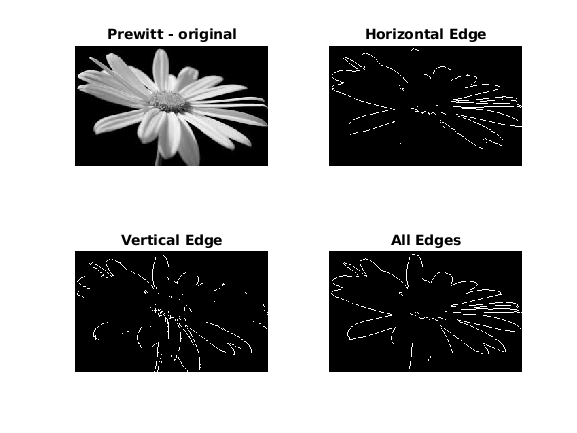

% Apply Prewitt Operator

clc;
figure;
subplot(2,2,1);imshow(myimage); title('Prewitt - original');

prewitthr = edge(myimage,'prewitt','horizontal');
subplot(2,2,2);imshow(prewitthr,[]); title('Horizontal Edge');

prewittvr = edge(myimage,'prewitt','vertical');
subplot(2,2,3);imshow(prewittvr,[]); title('Vertical Edge');

prewittvrthr = edge(myimage,'prewitt','both');
subplot(2,2,4);imshow(prewittvrthr,[]); title('All Edges');

## Image Edge Detection - Different threshold

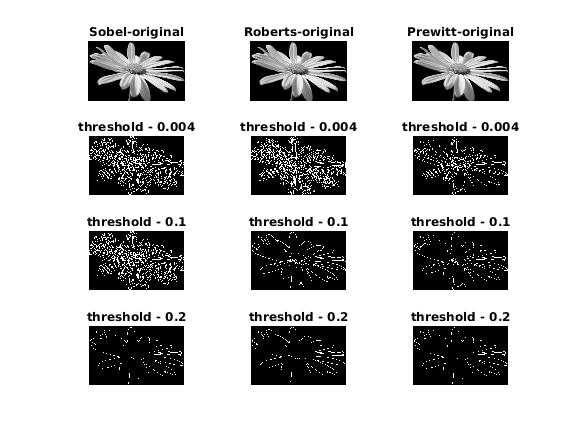

% Apply Sobel Operator

clc;

figure;
subplot(4,3,1);imshow(myimage); title('Sobel-original');

% Display only the horizontal Edges
sobelhz = edge(myimage,'sobel',0.004);
subplot(4,3,4);imshow(sobelhz,[]); title('threshold - 0.004');
% Display only the vertical Edges
sobelvrt = edge(myimage,'sobel',0.1);
subplot(4,3,7);imshow(sobelhz,[]); title('threshold - 0.1');
% Display both horizontal and vertical Edges
sobelvrthz = edge(myimage,'sobel',0.2);
subplot(4,3,10);imshow(sobelvrthz,[]); title('threshold - 0.2');



% Apply Roberts Operator
subplot(4,3,2);imshow(myimage); title('Roberts-original');

robertshz = edge(myimage,'roberts',0.004);
subplot(4,3,5);imshow(robertshz,[]); title('threshold - 0.004');
robertsvr = edge(myimage,'roberts',0.1);
subplot(4,3,8);imshow(robertsvr,[]); title('threshold - 0.1');
robertvrthz = edge(myimage,'roberts',0.2);
subplot(4,3,11);imshow(robertvrthz,[]); title('threshold - 0.2');


% Apply Prewitt Operator
subplot(4,3,3);imshow(myimage); title('Prewitt-original');

prewitthr = edge(myimage,'prewitt',0.04);
subplot(4,3,6);imshow(prewitthr,[]); title('threshold - 0.004');
prewittvr = edge(myimage,'prewitt',0.1);
subplot(4,3,9);imshow(prewittvr,[]); title('threshold - 0.1');
prewittvrthr = edge(myimage,'prewitt',0.2);
subplot(4,3,12);imshow(prewittvrthr,[]); title('threshold - 0.2');

## Image Edge Detection - Different Kernel size (Smaller and larger masks)

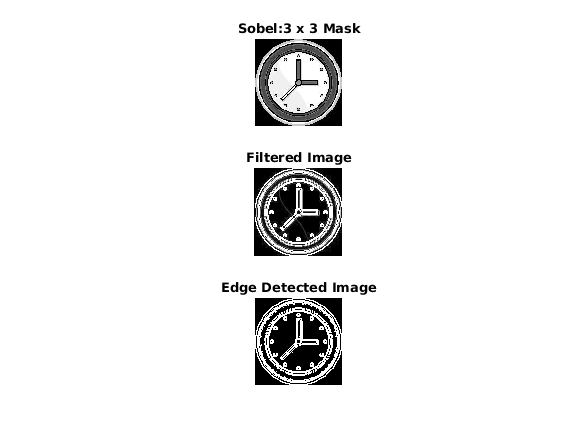

% Sobel for 3 x 3 mask

clc;
input_image = imread('clock.jpg'); 
input_image = uint8(input_image); 
input_image = rgb2gray(input_image); 
figure;
subplot(3,1,1);imshow(input_image); title('Sobel:3 x 3 Mask'); 
input_image = double(input_image);

% Pre-allocate the filtered_image matrix with zeros 
filtered_image = zeros(size(input_image)); 

% Sobel Operator Mask 
Mx = [-1 0 1; -2 0 2; -1 0 1]; 
My = [-1 -2 -1; 0 0 0; 1 2 1]; 

% Edge Detection Process 

% When i = 1 and j = 1, then filtered_image pixel position will be filtered_image(2, 2) 
% The mask is of 3x3, so we need to traverse to filtered_image(size(input_image, 1) - 2 , size(input_image, 2) - 2) 
% Thus we are not considering the borders. 

for i = 1:size(input_image, 1) - 2 
    for j = 1:size(input_image, 2) - 2 
  
        % Gradient approximations 
        Gx = sum(sum(Mx.*input_image(i:i+2, j:j+2))); 
        Gy = sum(sum(My.*input_image(i:i+2, j:j+2))); 
        
        % Calculate magnitude of vector 
        filtered_image(i+1, j+1) = sqrt(Gx.^2 + Gy.^2); 
         
    end
end

% Displaying Filtered Image 
filtered_image = uint8(filtered_image); 
subplot(3,1,2);imshow(filtered_image); title('Filtered Image'); 

% Define a threshold value 
thresholdValue = 100; % varies between [0 255] 
output_image = max(filtered_image, thresholdValue); 
output_image(output_image == round(thresholdValue)) = 0; 

% Displaying Output Image 
output_image = imbinarize(output_image); 
subplot(3,1,3);imshow(output_image); title('Edge Detected Image'); 

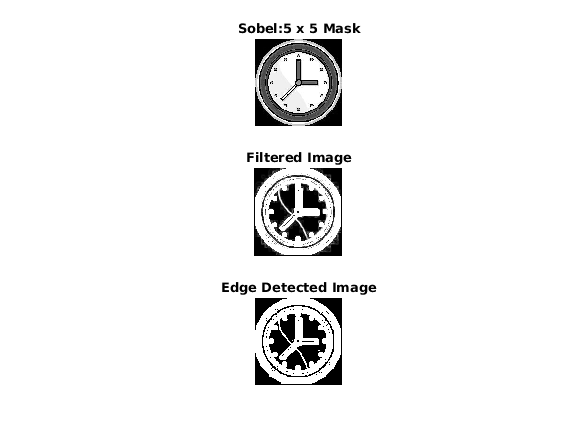

% Sobel for 5 x 5 mask

clc;
input_image1 = imread('clock.jpg'); 
input_image1 = uint8(input_image1); 
input_image1 = rgb2gray(input_image1); 
figure;
subplot(3,1,1);imshow(input_image1); title('Sobel:5 x 5 Mask'); 
input_image1 = double(input_image1);

% Pre-allocate the filtered_image matrix with zeros 
filtered_image1 = zeros(size(input_image1)); 

% Sobel Operator Mask 
Mx = [2 1 0 -1 -2;2 1 0 -1 -2;4 2 0 -2 -4;2 1 0 -1 -2;2 1 0 -1 -2]; 
My = [2 2 4 2 2;1 1 2 1 1;0 0 0 0 0;-1 -1 -2 -1 -1;-2 -2 -4 -2 -2]; 

% Edge Detection Process 
for i = 1:size(input_image1, 1) - 4

    for j = 1:size(input_image1, 2) - 4 
        % Gradient approximations 
        Gx = sum(sum(Mx.*input_image1(i:i+4, j:j+4))); 
        Gy = sum(sum(My.*input_image1(i:i+4, j:j+4))); 
        % Calculate magnitude of vector 
        filtered_image1(i+1, j+1) = sqrt(Gx.^2 + Gy.^2); 
    end

end

% Displaying Filtered Image 
filtered_image1 = uint8(filtered_image1); 
subplot(3,1,2);imshow(filtered_image1); title('Filtered Image'); 

% Define a threshold value 
thresholdValue1 = 100; % varies between [0 255] 
output_image1 = max(filtered_image1, thresholdValue1); 
output_image1(output_image1 == round(thresholdValue1)) = 0; 

% Displaying Output Image 
output_image1 = imbinarize(output_image1); 
subplot(3,1,3);imshow(output_image1); title('Edge Detected Image');

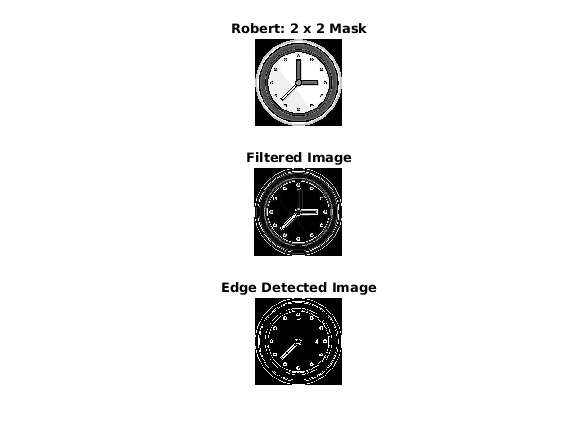

% Robert for 2 x 2 mask
 
input_image2 = imread('clock.jpg'); 
input_image2 = uint8(input_image2); 
input_image2 = rgb2gray(input_image2); 
figure;
subplot(3,1,1);imshow(input_image2); title('Robert: 2 x 2 Mask'); 
input_image2 = double(input_image2); 

% Pre-allocate the filtered_image matrix with zeros 
filtered_image2 = zeros(size(input_image2)); 

% Robert Operator Mask 
Mx = [1 0; 0 -1]; 
My = [0 1; -1 0]; 

% Edge Detection Process 
% When i = 1 and j = 1, then filtered_image pixel position will be filtered_image(1, 1) 
% The mask is of 2x2, so we need to traverse to filtered_image(size(input_image, 1) - 1 , size(input_image, 2) - 1) 

for i = 1:size(input_image2, 1) - 1 
    
    for j = 1:size(input_image2, 2) - 1  
        % Gradient approximations 
        Gx = sum(sum(Mx.*input_image2(i:i+1, j:j+1))); 
        Gy = sum(sum(My.*input_image2(i:i+1, j:j+1))); 
        
        % Calculate magnitude of vector  
        filtered_image2(i, j) = sqrt(Gx.^2 + Gy.^2); 
    end

end

% Displaying Filtered Image 
filtered_image2 = uint8(filtered_image2); 
subplot(3,1,2);imshow(filtered_image2); title('Filtered Image'); 

% Define a threshold value 
thresholdValue = 100; % varies between [0 255] 
output_image2 = max(filtered_image2, thresholdValue); 
output_image2(output_image2 == round(thresholdValue)) = 0; 

% Displaying Output Image 
output_image2 = imbinarize(output_image2); 
subplot(3,1,3);imshow(output_image2); title('Edge Detected Image');

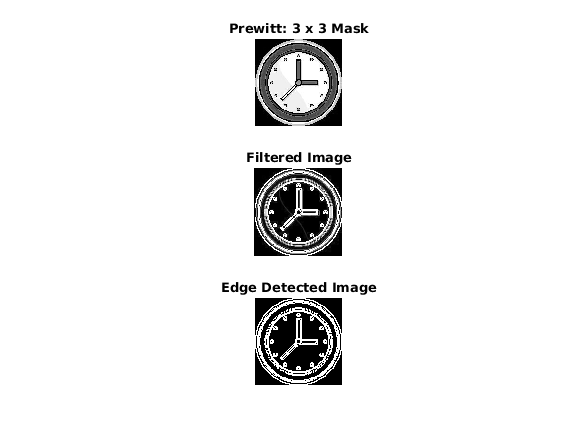

% Prewitt for 3 X 3 mask

input_image3 = imread('clock.jpg'); 
input_image3 = uint8(input_image3); 
input_image3 = rgb2gray(input_image3); 
figure;
subplot(3,1,1);imshow(input_image3); title('Prewitt: 3 x 3 Mask'); 
input_image3 = double(input_image3); 

% Pre-allocate the filtered_image matrix with zeros 
filtered_image3 = zeros(size(input_image3)); 

% Prewitt Operator Mask 
Mx = [-1 0 1; -1 0 1; -1 0 1]; 
My = [-1 -1 -1; 0 0 0; 1 1 1];

% Edge Detection Process 
for i = 1:size(input_image3, 1) - 2 
    
    for j = 1:size(input_image3, 2) - 2 
        % Gradient approximations 
        Gx = sum(sum(Mx.*input_image3(i:i+2, j:j+2))); 
        Gy = sum(sum(My.*input_image3(i:i+2, j:j+2))); 
        % Calculate magnitude of vector 
        filtered_image3(i+1, j+1) = sqrt(Gx.^2 + Gy.^2);  
    end

end

% Displaying Filtered Image 
filtered_image3 = uint8(filtered_image3); 
subplot(3,1,2); imshow(filtered_image3); title('Filtered Image'); 

% Define a threshold value 
thresholdValue = 100; % varies between [0 255] 
output_image3= max(filtered_image3, thresholdValue); 
output_image3(output_image3 == round(thresholdValue)) = 0; 

% Displaying Output Image 
output_image3 = imbinarize(output_image3); 
subplot(3,1,3); imshow(output_image3); title('Edge Detected Image');

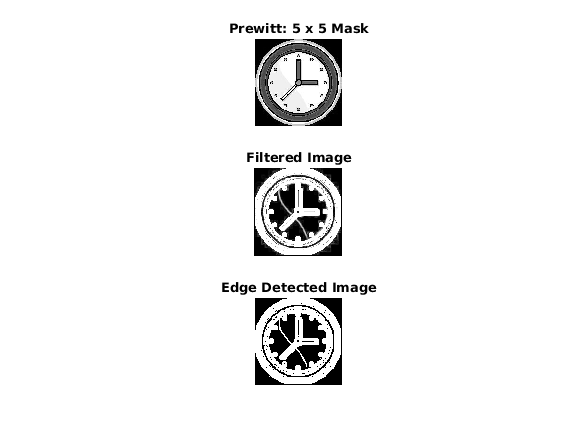

% Prewitt for 5 X 5 mask

input_image4 = imread('clock.jpg');
input_image4 = uint8(input_image4); 
input_image4 = rgb2gray(input_image4); 
figure;
subplot(3,1,1);imshow(input_image4); title('Prewitt: 5 x 5 Mask'); 
input_image4 = double(input_image4); 

% Pre-allocate the filtered_image matrix with zeros 
filtered_image4 = zeros(size(input_image4)); 

% Prewitt Operator Mask
Mx = [2 2 2 2 2;1 1 1 1 1;0 0 0 0 0;-1 -1 -1 -1 -1;-2 -2 -2 -2 -2]; 
My = [-2 -1 0 2 1;-2 -1 0 2 1;-2 -1 0 2 1;-2 -1 0 2 1;-2 -1 0 2 1]; 

% Edge Detection Process 
for i = 1:size(input_image4, 1) - 4 
    
    for j = 1:size(input_image4, 2) - 4
        % Gradient approximations 
        Gx = sum(sum(Mx.*input_image4(i:i+4, j:j+4))); 
        Gy = sum(sum(My.*input_image4(i:i+4, j:j+4))); 
        
        % Calculate magnitude of vector 
        filtered_image4(i+1, j+1) = sqrt(Gx.^2 + Gy.^2); 
    end
 
end

% Displaying Filtered Image 
filtered_image4 = uint8(filtered_image4); 
subplot(3,1,2); imshow(filtered_image4); title('Filtered Image'); 

% Define a threshold value 
thresholdValue = 100; % varies between [0 255] 
output_image4= max(filtered_image4, thresholdValue); 
output_image4(output_image4 == round(thresholdValue)) = 0; 

% Displaying Output Image 
output_image4 = imbinarize(output_image4); 
subplot(3,1,3); imshow(output_image4); title('Edge Detected Image');